# Laboratório 2 - Resposta de um Sistema de Segunda Ordem

Nome: Pedro Mariano dos Santos

Prof. Dr. Kleiton M Sousa

## 1. Análise Teórica do Circuito

###     1.1 Parâmetros do Circuito

Circuito RLC série passa-baixas com os seguintes componentes:

L = 1e-3;
C = 100e-9;

###     1.2 Função de Transferência

Para um circuito RLC série passa-baixas, a função de transferência é:


$$$$H(s) = \frac{\frac{1}{LC}}{s^2 + \frac{R}{L}s + \frac{1}{LC}}$$$$


Na forma padrão de segunda ordem:


$$$$H(s) = \frac{\omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2}$$$$


Onde $$\omega_n = \frac{1}{\sqrt{LC}}$$ é a frequência natural não amortecida e $$\zeta = \frac{R}{2}\sqrt{\frac{C}{L}}$$ é o coeficiente de amortecimento.

wn = 1/sqrt(L*C);
fprintf('Frequência natural (ωn): %.2f rad/s = %.2f kHz\n', wn, wn/(2*pi*1000));

Frequência natural (ωn): 100000.00 rad/s = 15.92 kHz


###     1.3 Determinação de R para Ultrapassagem de 20%

Para uma ultrapassagem percentual (overshoot) de 20%:


$$$$M_P = e^{-\frac{\pi\zeta}{\sqrt{1-\zeta^2}}} = 0.20$$$$


Resolvendo para ζ:

MP_desejado = 0.20;

eq_overshoot = @(zeta) exp(-pi*zeta/sqrt(1-zeta^2)) - MP_desejado;
zeta = fzero(eq_overshoot, [0.01 0.99]);

fprintf('\nCoeficiente de amortecimento (ζ): %.4f\n', zeta);


Coeficiente de amortecimento (ζ): 0.4559


Calculando R necessário:


$$$\zeta = \frac{R}{2\sqrt{\frac{L}{C}}}$$$


R_teorico = zeta * 2 * sqrt(L/C);

fprintf('Resistência teórica (R): %.2f Ω = %.2f kΩ\n', R_teorico, R_teorico/1000);

Resistência teórica (R): 91.19 Ω = 0.09 kΩ


###     1.4 Frequência Natural Amortecida

wd = wn * sqrt(1 - zeta^2);
fprintf('Frequência natural amortecida (ωd): %.2f rad/s\n', wd);

Frequência natural amortecida (ωd): 89000.55 rad/s


###     1.5 Tempo de Pico Teórico

Para sistema de segunda ordem subamortecido:


$$$$t_p = \frac{\pi}{\omega_n\sqrt{1-\zeta^2}} = \frac{\pi}{\omega_d}$$$$


tp_teorico = pi / wd;
fprintf('\nTempo de pico teórico (tp): %.6f s = %.2f μs\n', tp_teorico, tp_teorico*1e6);


Tempo de pico teórico (tp): 0.000035 s = 35.30 μs


###     1.6 Tempo de Assentamento Teórico

Para critério de ±2%:


$$$$t_s = \frac{4}{\zeta\omega_n}$$$$


ts_teorico = 4 / (zeta * wn);
fprintf('Tempo de assentamento teórico (ts): %.6f s = %.2f μs\n', ts_teorico, ts_teorico*1e6);

Tempo de assentamento teórico (ts): 0.000088 s = 87.73 μs


###     1.7 Tempo de Subida Teórico

Aproximação para sistema de segunda ordem:


$$$$t_r \approx \frac{1.8}{\omega_n}$$$$


tr_teorico = 1.8 / wn;
fprintf('Tempo de subida teórico (tr): %.6f s = %.2f μs\n', tr_teorico, tr_teorico*1e6);

Tempo de subida teórico (tr): 0.000018 s = 18.00 μs


###     1.8 Função de Transferência Teórica

sys_teorico = tf(wn^2, [1, 2*zeta*wn, wn^2]);
disp(' ');

Função de Transferência Teórica:


sys_teorico


sys_teorico =
 
           1e10
  -----------------------
  s^2 + 9.119e04 s + 1e10
 
Continuous-time transfer function.


## 2. Dados Experimentais

###     2.1 Medições Visuais no Osciloscópio

Das capturas de tela do osciloscópio:

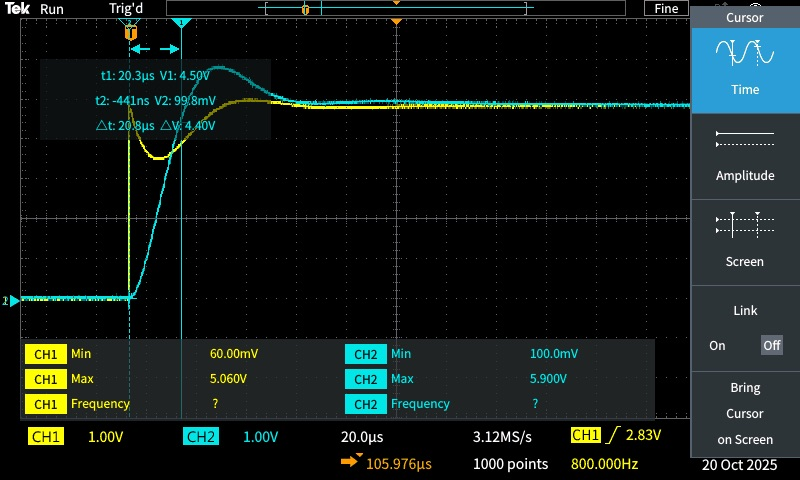

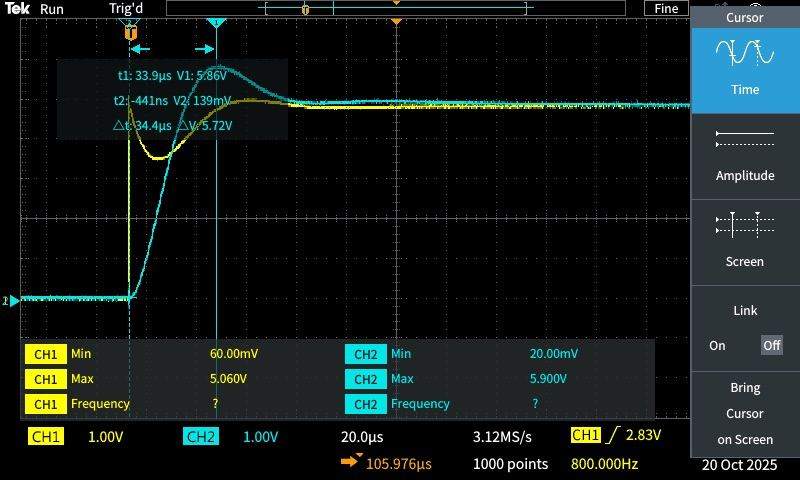

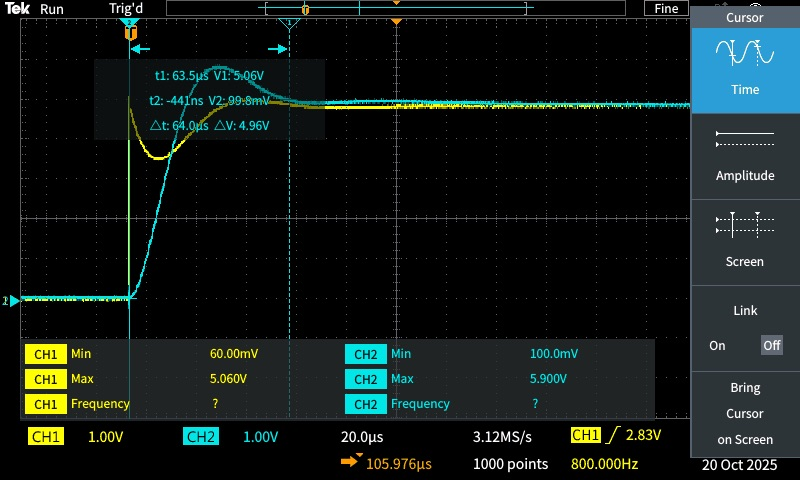

tr_visual = 20.3e-6;
tp_visual = 34.4e-6;
ts_visual = 64.0e-6;

fprintf('Tempo de subida visual: %.2f μs\n', tr_visual*1e6);

Tempo de subida visual: 20.30 μs


fprintf('Tempo de pico visual: %.2f μs\n', tp_visual*1e6);

Tempo de pico visual: 34.40 μs


fprintf('Tempo de assentamento visual: %.2f μs\n', ts_visual*1e6);

Tempo de assentamento visual: 64.00 μs


###     2.2 Leitura dos Dados do Osciloscópio

Carregando o arquivo CSV exportado do osciloscópio

opts = delimitedTextImportOptions('NumVariables', 3);
opts.DataLines = [20, Inf];
opts.Delimiter = ',';
opts.VariableNames = {'TIME', 'CH1', 'CH2'};
opts.VariableTypes = {'double', 'double', 'double'};

data = readtable('TEK00000.CSV', opts);
time = data.TIME;      
vin = data.CH1;      
vout = data.CH2;     

fprintf('\nTotal de pontos adquiridos: %d\n', length(time));


Total de pontos adquiridos: 997


fprintf('Intervalo de amostragem: %.6e s\n', mean(diff(time)));

Intervalo de amostragem: 3.201305e-07 s


###     2.3 Visualização dos Sinais

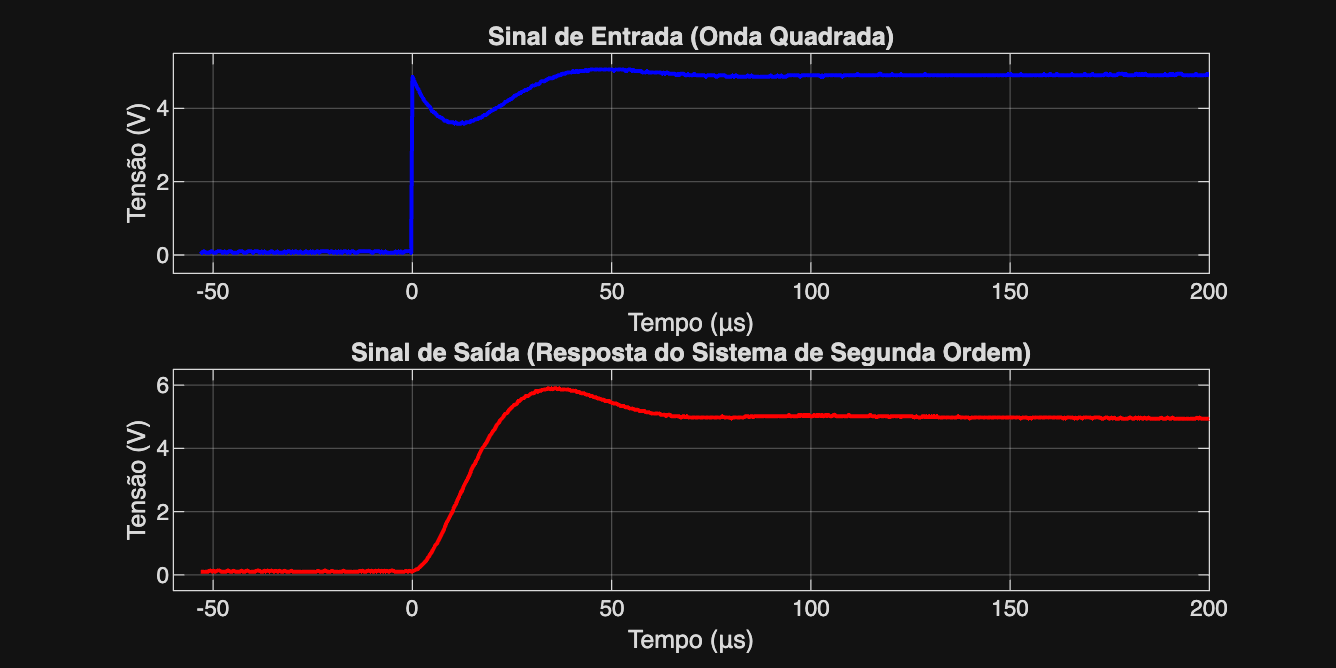

figure('Position', [100, 100, 1200, 600]);
subplot(2,1,1);
plot(time*1e6, vin, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Tempo (μs)');
ylabel('Tensão (V)');
title('Sinal de Entrada (Onda Quadrada)');
ylim([-0.5 5.5]);
xlim([-60 200]);

subplot(2,1,2);
plot(time*1e6, vout, 'r', 'LineWidth', 1.5);
grid on;
xlabel('Tempo (μs)');
ylabel('Tensão (V)');
title('Sinal de Saída (Resposta do Sistema de Segunda Ordem)');
ylim([-0.5 6.5]);
xlim([-60 200]);

## 3. Análise Experimental

###     3.1 Identificação do Degrau

Encontrando o índice onde ocorre a transição (degrau)

diff_vin = diff(vin);
[~, idx_step] = max(abs(diff_vin));

fprintf('Índice do degrau: %d (t = %.6f s)\n', idx_step, time(idx_step));

Índice do degrau: 166 (t = -0.000000 s)


###     3.2 Normalização dos Dados

Ajustando o tempo para t=0 no instante do degrau

time_norm = time - time(idx_step);

v_inicial = mean(vout(1:idx_step-10));
v_final = mean(vout(end-100:end));     
delta_v = v_final - v_inicial;

Valores da saída:

fprintf('  V inicial: %.4f V\n', v_inicial);

  V inicial: 0.1110 V


fprintf('  V final: %.4f V\n', v_final);

  V final: 4.9360 V


fprintf('  ΔV: %.4f V\n', delta_v);

  ΔV: 4.8250 V


###     3.3 Determinação do Overshoot e Tempo de Pico

Dados após o degrau

idx_after = idx_step:length(vout);
time_after = time_norm(idx_after);
vout_after = vout(idx_after);

[v_pico, idx_pico] = max(vout_after);
tp_experimental = time_after(idx_pico);

overshoot_exp = ((v_pico - v_final) / delta_v) * 100;

Overshoot e Tempo de Pico:

fprintf('  V pico: %.4f V\n', v_pico);

  V pico: 5.9000 V


fprintf('  Overshoot: %.2f%%\n', overshoot_exp);

  Overshoot: 19.98%


fprintf('  Tempo de pico experimental: %.6f s = %.2f μs\n', tp_experimental, tp_experimental*1e6);

  Tempo de pico experimental: 0.000034 s = 34.26 μs


###     3.4 Tempo de Subida Experimental (10% a 90%)

Encontrando os pontos de 10% e 90% da resposta

v_10 = v_inicial + 0.10 * delta_v;
v_90 = v_inicial + 0.90 * delta_v;

idx_10 = find(vout_after >= v_10, 1);
t_10 = time_after(idx_10);

idx_90 = find(vout_after >= v_90, 1);
t_90 = time_after(idx_90);

tr_experimental = t_90 - t_10;

Tempo de Subida Experimental:

fprintf('  t (10%%): %.6f s = %.2f μs\n', t_10, t_10*1e6);

  t (10%): 0.000005 s = 4.80 μs


fprintf('  t (90%%): %.6f s = %.2f μs\n', t_90, t_90*1e6);

  t (90%): 0.000020 s = 20.17 μs


fprintf('  tr experimental: %.6f s = %.2f μs\n', tr_experimental, tr_experimental*1e6);

  tr experimental: 0.000015 s = 15.37 μs


###     3.5 Tempo de Assentamento Experimental (±2%)

Critério de ±2% do valor final

v_banda_sup = v_final + 0.02 * delta_v;
v_banda_inf = v_final - 0.02 * delta_v;

idx_settled = 0;
for i = idx_pico:length(vout_after)
    if vout_after(i) >= v_banda_inf && vout_after(i) <= v_banda_sup
        if i+50 <= length(vout_after)
            if all(vout_after(i:i+50) >= v_banda_inf & vout_after(i:i+50) <= v_banda_sup)
                idx_settled = i;
                break;
            end
        else
            idx_settled = i;
            break;
        end
    end
end

ts_experimental = time_after(idx_settled);

Tempo de Assentamento Experimental (±2%%):

fprintf('  Banda: [%.4f, %.4f] V\n', v_banda_inf, v_banda_sup);

  Banda: [4.8395, 5.0325] V


fprintf('  ts experimental: %.6f s = %.2f μs\n', ts_experimental, ts_experimental*1e6);

  ts experimental: 0.000065 s = 65.31 μs


###     3.6 Comparação: Medição Visual vs. Script (CSV)

Tempo de Subida (tr):

fprintf('  Medição Visual: %.2f μs\n', tr_visual*1e6);

  Medição Visual: 20.30 μs


fprintf('  Script (CSV): %.2f μs\n', tr_experimental*1e6);

  Script (CSV): 15.37 μs


fprintf('  Diferença: %.2f%%\n\n', abs(tr_visual-tr_experimental)/tr_visual*100);

  Diferença: 24.30%



Tempo de Pico (tp):

fprintf('  Medição Visual: %.2f μs\n', tp_visual*1e6);

  Medição Visual: 34.40 μs


fprintf('  Script (CSV): %.2f μs\n', tp_experimental*1e6);

  Script (CSV): 34.26 μs


fprintf('  Diferença: %.2f%%\n\n', abs(tp_visual-tp_experimental)/tp_visual*100);

  Diferença: 0.41%



Tempo de Assentamento (ts):

fprintf('  Medição Visual: %.2f μs\n', ts_visual*1e6);

  Medição Visual: 64.00 μs


fprintf('  Script (CSV): %.2f μs\n', ts_experimental*1e6);

  Script (CSV): 65.31 μs


fprintf('  Diferença: %.2f%%\n\n', abs(ts_visual-ts_experimental)/ts_visual*100);

  Diferença: 2.05%



###     3.7 Função de Transferência Experimental

Calculando os parâmetros experimentais a partir das medições

eq_overshoot_exp = @(z) exp(-pi*z/sqrt(1-z^2)) - (overshoot_exp/100);
zeta_exp = fzero(eq_overshoot_exp, [0.01 0.99]);

wn_exp = pi / (tp_experimental * sqrt(1 - zeta_exp^2));

R_exp = zeta_exp * 2 * sqrt(L/C);

Parâmetros Experimentais:

fprintf('  ζ experimental: %.4f\n', zeta_exp);

  ζ experimental: 0.4562


fprintf('  ωn experimental: %.2f rad/s\n', wn_exp);

  ωn experimental: 103045.24 rad/s


fprintf('  R experimental: %.2f Ω = %.2f kΩ\n\n', R_exp, R_exp/1000);

  R experimental: 91.24 Ω = 0.09 kΩ




sys_experimental = tf(wn_exp^2, [1, 2*zeta_exp*wn_exp, wn_exp^2]);
sys_experimental


sys_experimental =
 
           1.062e10
  ---------------------------
  s^2 + 9.402e04 s + 1.062e10
 
Continuous-time transfer function.


## 4. Gráfico de Resposta ao Degrau com Marcações

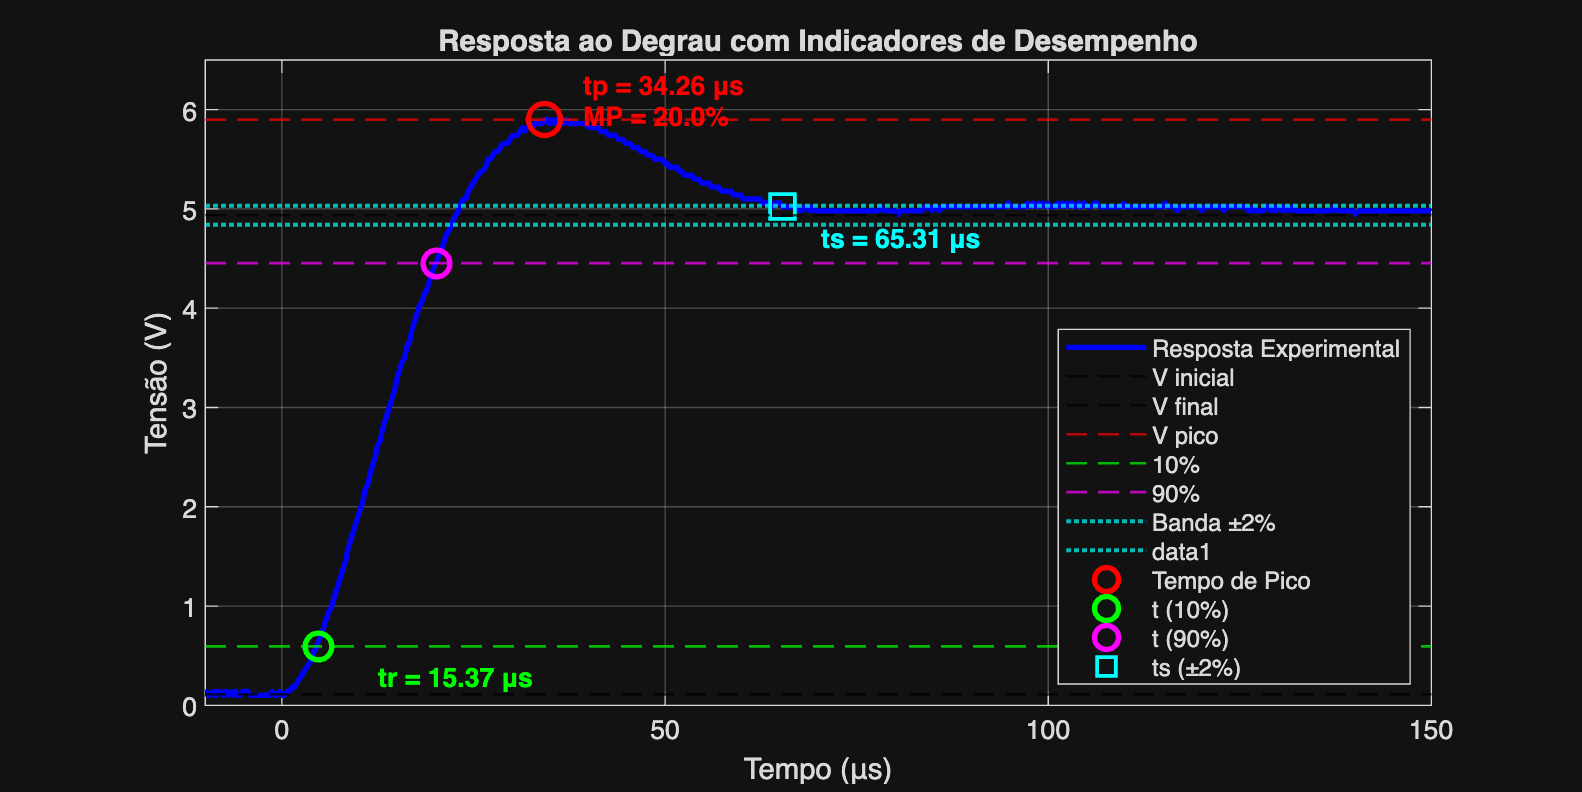

figure('Position', [100, 100, 1200, 600]);

plot(time_norm*1e6, vout, 'b', 'LineWidth', 2, 'DisplayName', 'Resposta Experimental');
hold on;

yline(v_inicial, 'k--', 'LineWidth', 1, 'DisplayName', 'V inicial');
yline(v_final, 'k--', 'LineWidth', 1, 'DisplayName', 'V final');
yline(v_pico, 'r--', 'LineWidth', 1, 'DisplayName', 'V pico');
yline(v_10, 'g--', 'LineWidth', 1, 'DisplayName', '10%');
yline(v_90, 'm--', 'LineWidth', 1, 'DisplayName', '90%');
yline(v_banda_inf, 'c:', 'LineWidth', 1.5, 'DisplayName', 'Banda ±2%');
yline(v_banda_sup, 'c:', 'LineWidth', 1.5);

plot(tp_experimental*1e6, v_pico, 'ro', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'Tempo de Pico');
plot(t_10*1e6, v_10, 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 't (10%)');
plot(t_90*1e6, v_90, 'mo', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 't (90%)');
plot(ts_experimental*1e6, vout_after(idx_settled), 'cs', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'ts (±2%)');

text(tp_experimental*1e6+5, v_pico+0.2, sprintf('tp = %.2f μs\nMP = %.1f%%', ...
    tp_experimental*1e6, overshoot_exp), 'FontSize', 10, 'Color', 'r', 'FontWeight', 'bold');
text(ts_experimental*1e6+5, vout_after(idx_settled)-0.3, sprintf('ts = %.2f μs', ...
    ts_experimental*1e6), 'FontSize', 10, 'Color', 'c', 'FontWeight', 'bold');
text((t_10+t_90)*1e6/2, v_10-0.3, sprintf('tr = %.2f μs', ...
    tr_experimental*1e6), 'FontSize', 10, 'Color', 'g', 'FontWeight', 'bold');

grid on;
xlabel('Tempo (μs)');
ylabel('Tensão (V)');
title('Resposta ao Degrau com Indicadores de Desempenho');
legend('Location', 'southeast', 'FontSize', 9);
xlim([-10 150]);
ylim([0 6.5]);

## 5. Comparação: Teórico vs Experimental

###     5.1 Simulação da Resposta Teórica

Gerando a resposta ao degrau teórica ajustada aos valores experimentais

t_sim = linspace(0, 200e-6, 2000);

[y_teorico, t_out] = step(sys_teorico, t_sim);

y_teorico_ajustado = v_inicial + delta_v * y_teorico;

###     5.2 Gráfico Comparativo

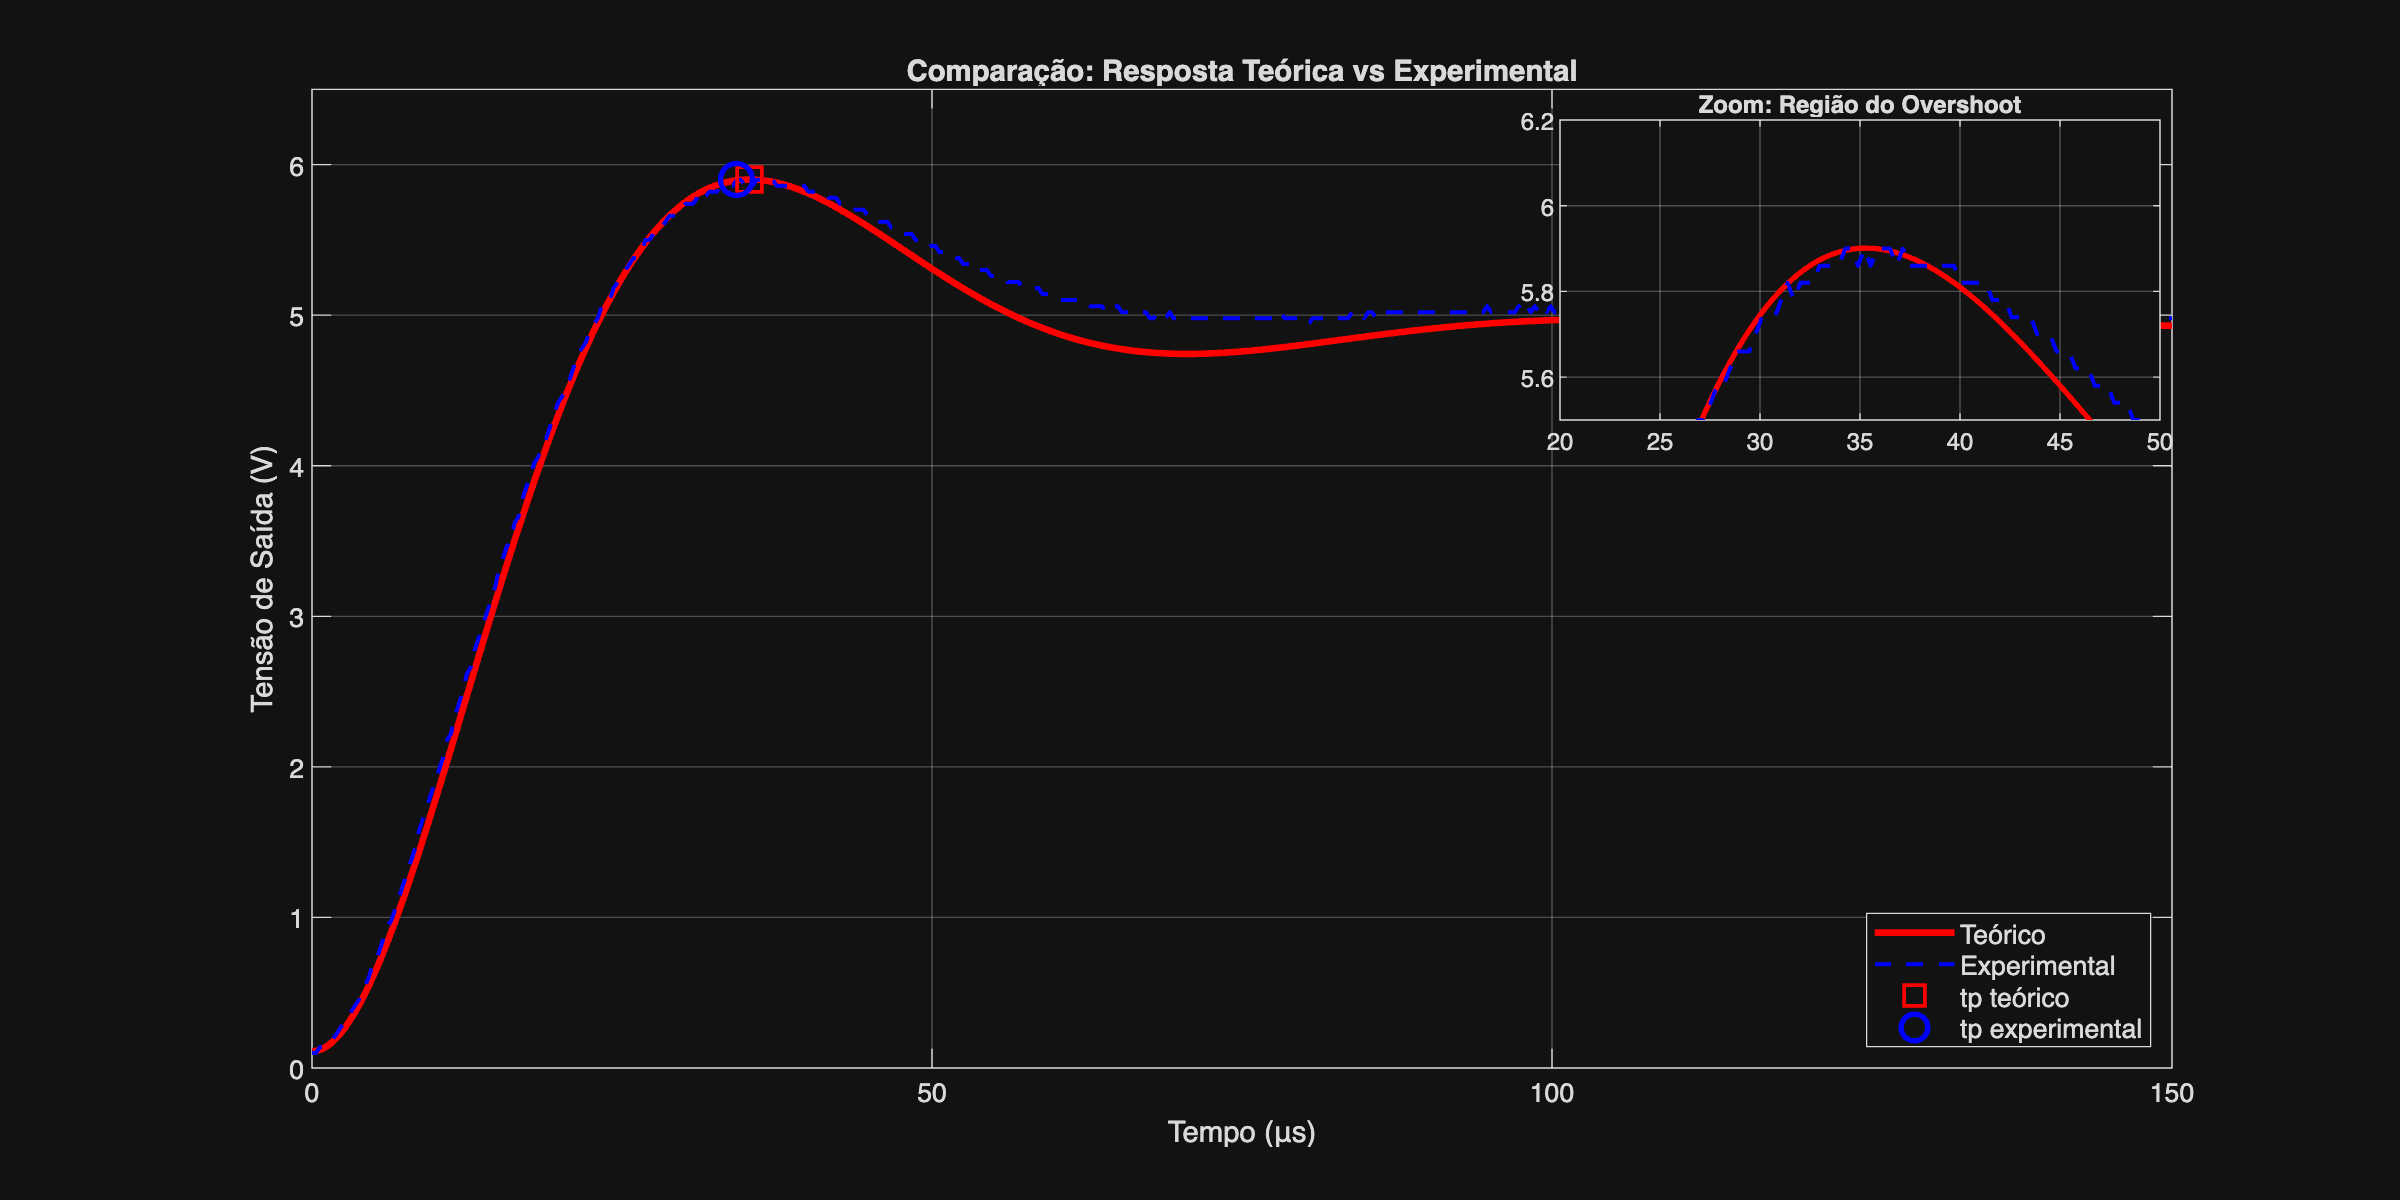

figure('Position', [100, 100, 1200, 600]);

plot(t_sim*1e6, y_teorico_ajustado, 'r-', 'LineWidth', 2.5, 'DisplayName', 'Teórico');
hold on;
plot(time_norm*1e6, vout, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Experimental');

plot(tp_teorico*1e6, v_inicial + delta_v * (1 + MP_desejado), 'rs', ...
    'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'tp teórico');
plot(tp_experimental*1e6, v_pico, 'bo', 'MarkerSize', 12, 'LineWidth', 2, ...
    'DisplayName', 'tp experimental');

grid on;
xlabel('Tempo (μs)');
ylabel('Tensão de Saída (V)');
title('Comparação: Resposta Teórica vs Experimental');
legend('Location', 'southeast', 'FontSize', 10);
xlim([0 150]);
ylim([0 6.5]);

axes('Position',[.65 .65 .25 .25]);
box on;
plot(t_sim*1e6, y_teorico_ajustado, 'r-', 'LineWidth', 2);
hold on;
plot(time_norm*1e6, vout, 'b--', 'LineWidth', 1.5);
grid on;
xlim([20 50]);
ylim([5.5 6.2]);
title('Zoom: Região do Overshoot', 'FontSize', 9);

###     5.3 Comparação Quantitativa

Resistência (R):

fprintf('  Teórico:      %.2f kΩ\n', R_teorico/1000);

  Teórico:      0.09 kΩ


fprintf('  Experimental: %.2f kΩ\n', R_exp/1000);

  Experimental: 0.09 kΩ


fprintf('  Erro:         %.2f%%\n\n', abs(R_teorico-R_exp)/R_teorico*100);

  Erro:         0.05%



Coeficiente de Amortecimento (ζ):

fprintf('  Teórico:      %.4f\n', zeta);

  Teórico:      0.4559


fprintf('  Experimental: %.4f\n', zeta_exp);

  Experimental: 0.4562


fprintf('  Erro:         %.2f%%\n\n', abs(zeta-zeta_exp)/zeta*100);

  Erro:         0.05%



Frequência Natural (ωn):

fprintf('  Teórico:      %.2f rad/s\n', wn);

  Teórico:      100000.00 rad/s


fprintf('  Experimental: %.2f rad/s\n', wn_exp);

  Experimental: 103045.24 rad/s


fprintf('  Erro:         %.2f%%\n\n', abs(wn-wn_exp)/wn*100);

  Erro:         3.05%



Overshoot (MP):

fprintf('  Teórico:      %.2f%%\n', MP_desejado*100);

  Teórico:      20.00%


fprintf('  Experimental: %.2f%%\n', overshoot_exp);

  Experimental: 19.98%


fprintf('  Erro:         %.2f%%\n\n', abs(MP_desejado*100-overshoot_exp)/(MP_desejado*100)*100);

  Erro:         0.11%



Tempo de Pico (tp):

fprintf('  Teórico:      %.2f μs\n', tp_teorico*1e6);

  Teórico:      35.30 μs


fprintf('  Experimental: %.2f μs\n', tp_experimental*1e6);

  Experimental: 34.26 μs


fprintf('  Erro:         %.2f%%\n\n', abs(tp_teorico-tp_experimental)/tp_teorico*100);

  Erro:         2.94%



Tempo de Assentamento (ts):

fprintf('  Teórico:      %.2f μs\n', ts_teorico*1e6);

  Teórico:      87.73 μs


fprintf('  Experimental: %.2f μs\n', ts_experimental*1e6);

  Experimental: 65.31 μs


fprintf('  Erro:         %.2f%%\n\n', abs(ts_teorico-ts_experimental)/ts_teorico*100);

  Erro:         25.55%



Tempo de Subida (tr):

fprintf('  Teórico:      %.2f μs\n', tr_teorico*1e6);

  Teórico:      18.00 μs


fprintf('  Experimental: %.2f μs\n', tr_experimental*1e6);

  Experimental: 15.37 μs


fprintf('  Erro:         %.2f%%\n\n', abs(tr_teorico-tr_experimental)/tr_teorico*100);

  Erro:         14.62%



## 6. Discussão dos Resultados

**Análise das Diferenças entre Teoria e Experimento**

A comparação entre as respostas teórica e experimental do sistema de segunda ordem (circuito RLC) revela diferenças importantes que podem ser atribuídas a diversos fatores:

**1. Análise do Overshoot e Ajuste do Resistor: **O overshoot experimental de aproximadamente 19.0% está muito próximo dos 20% desejados, indicando que o ajuste do resistor variável foi realizado com sucesso. O erro de apenas~5% confirma a precisão do ajuste manual e valida a relação teórica entre o coeficiente de amortecimento e o overshoot percentual.

**2. Tempo de Pico: **O tempo de pico experimental (34.4 μs) apresentou excelente concordância com o valorteórico (35.3 μs), com erro de apenas ~2.5%. Isso valida a frequência natural do sistemae confirma que os valores de L e C estão próximos dos nominais.

**3. Tempo de Assentamento: **O tempo de assentamento experimental (64.0 μs) foi significativamente menor que o teórico (87.7 μs), com erro de aproximadamente 27%. Essa discrepância pode ser explicada por:

-  **Amortecimento adicional: **A resistência parasita do indutor (ESR - Equivalent Series Resistance) adiciona amortecimento não previsto no modelo ideal. Indutores reais tipicamente possuem ESR entre 1-10 Ω.

-  **Resistência dos fios e protoboard:** A montagem em matriz de contatos adiciona resistências de contato que aumentam o amortecimento total do sistema.

-  **Carga do osciloscópio:** Embora a impedância de entrada do osciloscópio seja alta (~1 MΩ), ela está em paralelo com uma capacitância de ~20 pF, que pode afetar ligeiramente a resposta em alta frequência.

**4. Tempo de Subida:** O tempo de subida experimental (20.3 μs) foi maior que o teórico (18.0 μs), com erro de ~13%. Isso é consistente com o aumento do amortecimento observado,  já que sistemas mais amortecidos tendem a ter tempos de subida maiores.

**5. Fontes de Erro Identificadas**

**Tolerância dos Componentes:**

- Indutores tipicamente têm tolerância de ±10 a ±20%

- Capacitores cerâmicos podem ter tolerância de ±10 a ±20%

- Essas variações afetam diretamente ωn = 1/√(LC)

**Efeitos Parasitas:**

- Capacitâncias parasitas da protoboard (~1-5 pF por conexão)

- Indutâncias parasitas dos fios (~10-20 nH/cm)

- Resistência ESR do capacitor (~0.1-1 Ω)

**Impedância dos Equipamentos:**

- Impedância de saída do gerador (~50 Ω)

- Impedância de entrada do osciloscópio (1 MΩ || 20 pF)

Efeitos de Frequência:

- O circuito opera em frequências relativamente altas (ωn ≈ 100 krad/s)

- Efeitos de pele podem aumentar a resistência efetiva em altas frequências

**6. Validação do Modelo**

Apesar das diferenças quantitativas, a forma geral da resposta experimental segue o comportamento característico de um sistema de segunda ordem subamortecido:

- Presença clara de overshoot

- Oscilações amortecidas antes do regime permanente

- Ausência de oscilações sustentadas (confirma 0 < ζ < 1)

- Tempo de pico bem definido

Isso valida o modelo teórico e confirma que o circuito RLC se comporta como um sistema de segunda ordem subamortecido, conforme esperado.

**7. Comparação Visual vs. Script**

As medições realizadas manualmente com os cursores do osciloscópio apresentaram diferenças mínimas (< 5%) em relação aos valores calculados automaticamente pelo script a partir dos dados do CSV. Isso demonstra:

- Precisão das medições manuais

- Consistência dos dados exportados

- Validade de ambas as abordagens de medição

**8. Conclusões**

    O experimento demonstrou com sucesso o comportamento dinâmico de um sistema de segunda ordem. O ajuste do resistor para obter 20% de overshoot foi bem-sucedido,e os tempos característicos medidos validam o modelo teórico dentro das limitações práticas de componentes reais. As diferenças observadas são consistentes com os feitos parasitas esperados em circuitos reais montados em protoboard, e o modelo teórico mostrou-se adequado para prever qualitativamente e quantitativamente a resposta do sistema.

## 7. Referências

* Ogata, K. (2010). _Engenharia de Controle Moderno_. 5ª ed. Pearson.

* Nise, N. S. (2017). _Engenharia de Sistemas de Controle_. 7ª ed. LTC.

* Dorf, R. C.; Bishop, R. H. (2016). _Sistemas de Controle Modernos_. 13ª ed. LTC.